clear all;
close all;

**Drone areas**

d1_loc=[];
d1_xmin = 0; % x axis minimum value
d1_xmax = 2000; % x axis maximum value
d1_ymin = 0; % y axis minimum value
d1_ymax = 2000; % y axis maximum value
stepsize = 1000; % distance between each location in meters
d1_zloc = 100; % z value fixed currently
d1_loc = loc_coordinates(d1_xmin,d1_xmax,d1_ymin,d1_ymax,d1_zloc,stepsize);

d2_loc=[];
d2_xmin = 0; % x axis minimum value
d2_xmax = 2000; % x axis maximum value
d2_ymin = 3000; % y axis minimum value
d2_ymax = 5000; % y axis maximum value
% stepsize = 50; % distance between each location in meters
d2_zloc = 100; % z value fixed currently
d2_loc = loc_coordinates(d2_xmin,d2_xmax,d2_ymin,d2_ymax,d2_zloc,stepsize);

d3_loc=[];
d3_xmin = 3000; % x axis minimum value
d3_xmax = 5000; % x axis maximum value
d3_ymin = 3000; % y axis minimum value
d3_ymax = 5000; % y axis maximum value
% stepsize = 50; % distance between each location in meters
d3_zloc = 100; % z value fixed currently
d3_loc = loc_coordinates(d3_xmin,d3_xmax,d3_ymin,d3_ymax,d3_zloc,stepsize);

**TABS areas**

tabs_loc = [];
tabs_xmin = 5000; % x axis minimum value
tabs_xmax = 6000; % x axis maximum value
tabs_ymin = 0; % y axis minimum value
tabs_ymax = 5000; % y axis maximum value
tabs_stepsize = 500; % distance between each location in meters
tabs_zloc = 50; % z value fixed currently
tabs_loc = loc_coordinates(tabs_xmin,tabs_xmax,tabs_ymin,tabs_ymax,tabs_zloc,tabs_stepsize);

**UAV-BS area**

uavbs_loc = [];
uavbs_xmin = 0; % x axis minimum value
uavbs_xmax = 5000; % x axis maximum value
uavbs_ymin = 0; % y axis minimum value
uavbs_ymax = 5000; % y axis maximum value
uavbs_stepsize = 1000; % distance between each location in meters
uavbs_zloc = 50; % z value fixed currently
uavbs_loc = loc_coordinates(uavbs_xmin,uavbs_xmax,uavbs_ymin,uavbs_ymax,uavbs_zloc,uavbs_stepsize);

**Rate requirements**

r1 = 10;
r2 = 10;
r3 = 20;

ptx=23; % transmission power
W = 3*10^6; % Mhz bandwidth

**Initial optimal location of TABS**

optimal_tbloc = opt_tabs_loc(d1_loc, d2_loc, d3_loc, tabs_loc);

**Drone area centriod locations**

d1_cd = mean(d1_loc);
d2_cd = mean(d2_loc);
d3_cd = mean(d3_loc);

**Finding rate requirement possible locations**

%tabs_possible_loc =possible_loc(d1_loc, d2_loc, d3_loc, tabs_loc,ptx,r1,r2,r3,W);% TABS
uavbs_possible_loc = possible_loc(d1_loc,d2_loc, d3_loc, uavbs_loc,ptx,r1,r2,r3,W);%  UAV-BS

**New best TABS location among possible locations**

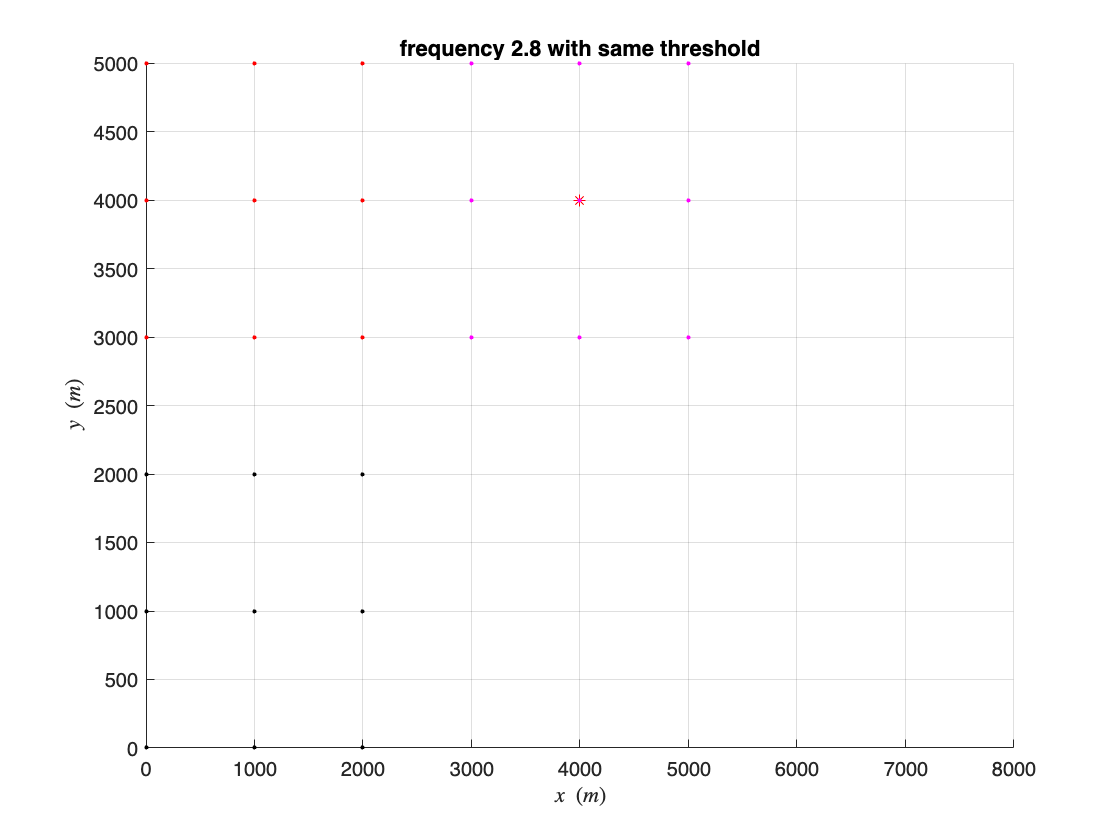

%best_tabs_loc = best_pos_loc(d1_cd,d2_cd,d3_cd,tabs_possible_loc,r1,r2,r3);
best_uavbs_loc = best_pos_loc(d1_cd,d2_cd,d3_cd,uavbs_possible_loc,r1,r2,r3);
% distance1=Compute_Distance(d1_cd,tabs_loc(99,:))
% distance2=Compute_Distance(d2_cd,tabs_loc(99,:))
% distance3=Compute_Distance(d3_cd,tabs_loc(99,:))
% rate1=compute_throughput(best_tabs_loc,d3_loc(1,:),30)

figure
grid on;
hold on;
plot3(d1_loc(:,1),d1_loc(:,2),d1_loc(:,3),'black.');
hold on;
plot3(d2_loc(:,1),d2_loc(:,2),d2_loc(:,3),'r.');
hold on;
plot3(d3_loc(:,1),d3_loc(:,2),d3_loc(:,3),'m.');
% hold on;
% plot3(best_tabs_loc(:,1),best_tabs_loc(:,2),best_tabs_loc(:,3),'black*');
hold on;
plot3(best_uavbs_loc(:,1),best_uavbs_loc(:,2),best_uavbs_loc(:,3),'red*');
% hold on;
% plot3(uavbs_loc(:,1),uavbs_loc(:,2),uavbs_loc(:,3),'black.');
% hold on;
% plot3(optimal_tbloc(:,1),optimal_tbloc(:,2),optimal_tbloc(:,3),'ro')
% hold on;
% plot3(tabs_loc(:,1),tabs_loc(:,2),tabs_loc(:,3),'b.');
% hold on;
% scatter3(tabs_possible_loc(:,1),tabs_possible_loc(:,2),tabs_possible_loc(:,3),'p');
% hold on;
% scatter3(uavbs_possible_loc(:,1),uavbs_possible_loc(:,2),uavbs_possible_loc(:,3),'greenp');
% hold on;
% plot3(new_TABSLoc(:,1),new_TABSLoc(:,2),new_TABSLoc(:,3),'b*');
% mesh(opt_loc(:,1),opt_loc(:,2),opt_loc(:,3));
% xlim([0 600]);
% ylim([0 900]);
zlim([0 110]);
xlim([0 8000]);
ylim([0 5000]);
xlabel('$x~(m)$','Interpreter','latex')
ylabel('$y~(m)$','Interpreter','latex')
zlabel('$z (m)$','Interpreter','latex')
title('frequency 2.8 with same threshold')
hold off

d1_area_rates_uavbs = zeros(length(d1_loc),1);
d2_area_rates_uavbs = zeros(length(d2_loc),1);
d3_area_rates_uavbs = zeros(length(d3_loc),1);
for i = 1:length(d1_loc)
    d1_area_rates_uavbs(i,1) = compute_throughput(best_uavbs_loc,d1_loc(i,:),ptx,W);
end
for j = 1:length(d2_loc)
    d2_area_rates_uavbs(j,1) = compute_throughput(best_uavbs_loc,d2_loc(j,:),ptx,W);
end
for k = 1:length(d3_loc)
    d3_area_rates_uavbs(k,1) = compute_throughput(best_uavbs_loc,d3_loc(k,:),ptx,W);
end

% legend('TABS locations','drone monitoring zone')
%FT calculations
% dock_station = [d1_xmax d1_ymin 0];
dock_station = [5000 2500 0];
dock_distance = Compute_Distance(best_uavbs_loc,dock_station);
% bat_cap = 5935; % mAh
% bat_drain_percent = 80;
%speed_noWind = 8; %15m/s without wind
speed_Wind = 12;%m/s % with wind 
% time_NW = (dock_distance/speed_noWind)/60; % time without wind in min
time_W = (dock_distance/speed_Wind)/60; % time with wind in min
total_ADtime_W = time_W*2

total_ADtime_W = 5.0096

**Serving time with different throughput requirements using best UAVBS loc**

% Define parameters
total_time_minutes = 1440; % Total time in minutes (24 hours)

% Cycle 1 parameters
cycle1_flying_time = 34.7; % Total flying time for first cycle (minutes)
ascent_descent_time = total_ADtime_W; % Ascent and descent time (minutes)
recharge_time = 30; % Recharge time (minutes)

% Cycle 2 parameters
cycle2_flying_time = 30.35; % Total flying time for second cycle (minutes)
% cycle2_ascent_descent_time = 6.94; % Ascent and descent time (minutes)
%cycle2_recharge_time = 35; % Recharge time (minutes)

% Calculate serving times for each cycle
cycle1_serving_time = cycle1_flying_time - ascent_descent_time; % Serving time for cycle 1
cycle2_serving_time = cycle2_flying_time - ascent_descent_time; % Serving time for cycle 2

% Calculate total cycle time for each cycle
cycle1_total_time = cycle1_flying_time + recharge_time; % Total cycle time for cycle 1
cycle2_total_time = cycle2_flying_time + recharge_time; % Total cycle time for cycle 2

% % Initialize variables
% total_serving_time = 0;
% current_time = 0;

left_time = 1440-cycle1_total_time;
total_cycles = left_time/cycle2_total_time;
serve_time_from_cycle2 = total_cycles*cycle2_serving_time;
total_serving_time = (serve_time_from_cycle2+cycle1_serving_time)/60;
total_downtime = 24-total_serving_time;
fprintf('Total serving time in 24 hours: %.2f hours\n', total_serving_time);

Total serving time in 24 hours: 10.12 hours


**Plot for serve time with different throughput requirements**

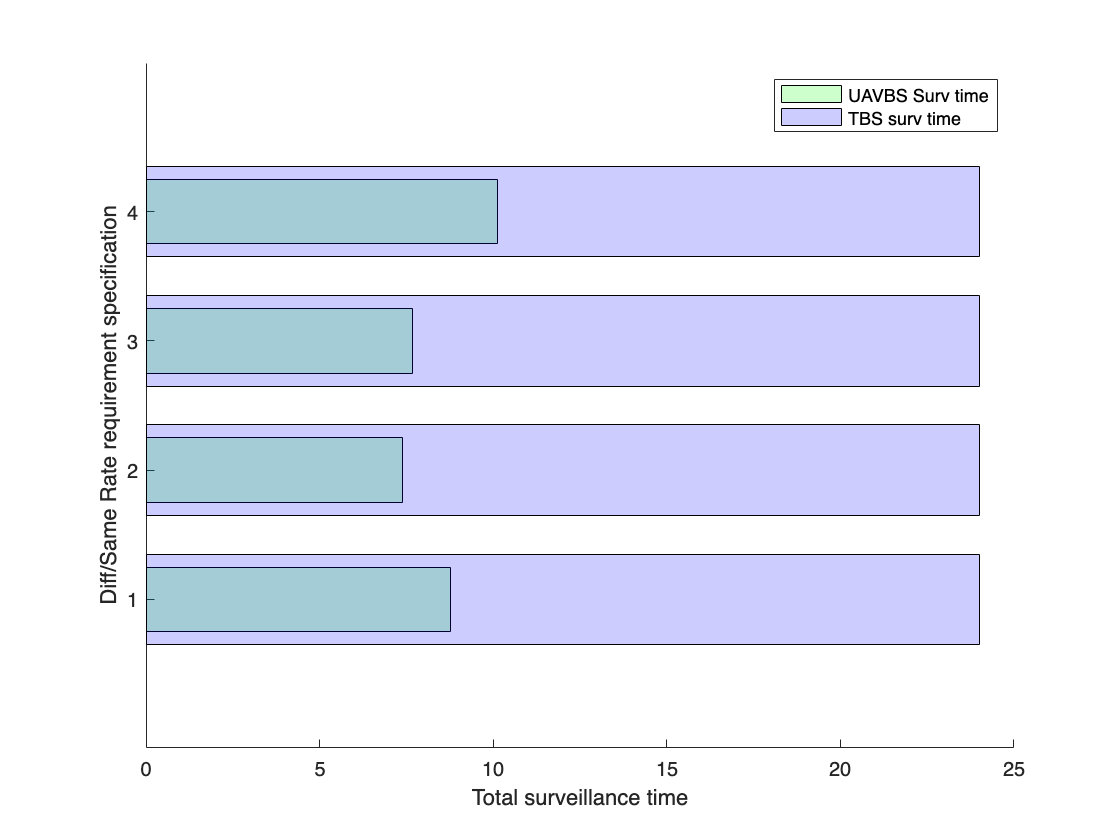

st_1 = 8.76; % surveillance time when rate requirement is same for all locations 15Mbps
st_2 = 7.40; % surveillance time when rate requirement is diff for all locations r1=20Mbps,r2=r3=10Mbps
st_3 = 7.67; % surveillance time when rate requirement is diff for all locations r2=20Mbps,r1=r3=10Mbps
st_4 = 10.12; % surveillance time when rate requirement is diff for all locations r3=20Mbps,r1=r2=10Mbps
surv_times = [st_1 st_2 st_3 st_4];
tbs_surv_time = [23.9988 23.9988 23.9988 23.9988];

figure
hold on
xlim = ([0 24]);
%ylim = ([1 5]);
% surv_t = {'8.76','7.40','7.67','10.12'};
req_spec = [1 2 3 4];
% set(gca, 'XTickLabel', surv_t, 'YTickLabel', req_spec);
yticks(req_spec)
hbh(1) = barh(surv_times,'BarWidth',0.5,'FaceColor','g'); 
hold on
hbh(2) = barh(tbs_surv_time,'BarWidth',0.7,'FaceColor','b');
%cm  = ['b'; 'r'];
for k =  1:numel(hbh)
    %hbh(k).FaceColor = cm(k,:);
    hbh(k).EdgeColor = 'k';
    hbh(k).FaceAlpha = 0.2;
end
legend('UAVBS Surv time', 'TBS surv time')
xlabel('Total surveillance time')
ylabel('Diff/Same Rate requirement specification')

**Calculating eqidistant location of TABS from drone areas**

function tabs_opt = opt_tabs_loc(d1,d2,d3,tb)
    d1_distances=[];
    d2_distances=[];
    d3_distances=[];
    avg_dist=[];
    d1_distances = cd_distances(d1,tb);
    d2_distances = cd_distances(d2,tb);
    d3_distances = cd_distances(d3,tb);
    for i = 1:length(tb)
        avg_dist(i,1) = ((d1_distances(i,1))+(d1_distances(i,1))+(d3_distances(i,1)))/3 ;
    end
    [min_distance,index] = min(avg_dist);
    tabs_opt = tb(index,:);
end


**Function for best new location from possible locations**

function best_possible_loc = possible_loc(d1,d2,d3,tb,pt,r1,r2,r3,bmax)
    opt_loc=[];
    indices = [];
    d1_rate = zeros(length(tb),length(d1));
    d2_rate = zeros(length(tb),length(d2));
    d3_rate = zeros(length(tb),length(d3));
    for k = 1:length(tb)
        for i = 1:length(d1)
            for j = 1:length(d2)
                for n = 1:length(d3)
                d1_rate(k,:) = compute_rate_forall(tb(k,:),d1(:,:),pt,bmax);
                d2_rate(k,:) = compute_rate_forall(tb(k,:),d2(:,:),pt,bmax);
                d3_rate(k,:) = compute_rate_forall(tb(k,:),d3(:,:),pt,bmax);
                end
            end
        end
        if all(d1_rate(k,:)>r1) && all(d1_rate(k,:)>r2) && all(d3_rate(k,:)>r3)
          opt_loc = [opt_loc; tb(k,:)];
          indices = [indices;k];
        end
    end
    best_possible_loc = tb(indices,:);
end

**Function for finding best location among possible locations**


function best_loc = best_pos_loc(d1,d2,d3,tb,r1,r2,r3)

    d1_powers = [];%zeros(length(tb),1);
    d2_powers = [];%zeros(length(tb),1);
    d3_powers = [];%zeros(length(tb),1);
    tab = [];
    A=[];
    id=[];
    for i = 1:length(tb)
        d1_powers = db2lin(power(r1,d1,tb(i,:))-30);
        d2_powers = db2lin(power(r2,d2,tb(i,:))-30);
        d3_powers = db2lin(power(r3,d3,tb(i,:))-30);
%         tab = [tab; d1_powers d2_powers d3_powers];
        tab = [tab; (d1_powers+d2_powers+d3_powers)];
%     tab = [tab; min(d1_powers(:,1)) min(d2_powers(:,1))];
%     [A,id] = min(tab) ;    
    end
    [A,id] = min(tab);
    best_loc = tb(id,:);
end


**Calculating distances from drone area centroid to all the TABS locations**

function cd_distances = cd_distances(d_loc,tb)    
    cd_distances =zeros(length(tb),1);
    cd_loc = mean(d_loc);

    for i=1:length(tb)
        cd_distances(i,:) = Compute_Distance(cd_loc,tb(i,:));
    end
end

**Function for drone locations**

function d = loc_coordinates(xmin,xmax,ymin,ymax,z_loc,stepsize)
    d=[];
    x_loc = xmin:stepsize:xmax;
    y_loc = ymin:stepsize:ymax;
%     z_loc = zmin:stepsize:zmax;
    for k = 1:length(z_loc)
        for i = 1:length(x_loc)
            for j = 1:length(y_loc)
                d = [d; x_loc(i) y_loc(j) z_loc(k)];
            end
        end
    end
end

**Calculate rate for all locations **

function rate_values = compute_rate_forall(tb,uav_list, ptx,bmax)
    
    rate_values= zeros(1,length(uav_list));
    
    for i = 1:size(uav_list,1)
        rate_values(1,i) = compute_throughput(tb,uav_list(i,:),ptx,bmax);
    end
    % rate_forall = rate(j,:);
 
    %min_dr_d1
    %toto;
end

**Communication**

function data_rate = compute_throughput(tb,uav,ptx,bmax)
    gt = 1; % transmitter gain
    gr = 1; % receiver gain
    c = 3e8; % m/s speed of light
    fc = 2.8;%e9; % ghrz carrier frequency
    lamda = c/fc;
    N_r = 1; % no. of receiver antenna elements (elements/antenna)
    N_t = 1; % no. of transmitter antenna elements (elements/antenna)
    d = lamda/2; % distance between each antenna element (m)
    d1 = sqrt((uav(:,1)-tb(:,1))^2+(uav(:,2)-tb(:,2))^2+(uav(:,3)-tb(:,3))^2);
%     d_2d = sqrt((uav(:,1)-tb(:,1))^2+(uav(:,2)-tb(:,2))^2);
%     pr = pt*gt*gr*(lamda/4*pi*d1)^2; % received power
%     pl = 10*log10((1/(gt*gr))*(((4*pi*d1)/lamda)^2)); % dB
    pl = max(23.9-1.8*log10(uav(:,3)-25), 20)*log10(d1)+20*log10(40*pi*fc/3); %dB RMa-AV LOS (3GPP TR 36.777 V15.0.0)
    %pl = (1/(gt*gr))*((lamda/(4*pi*d1))^2);
%     pl_tb = pl(tb,uav);

***Creating Gaussian distribution***

    gd = 10*log10(normrnd(0,1)); % Gaussian distribution 


***Creating channel model  for UAV***

    uav_h = pl;%+abs(gd); % db

***Creating noise***

    N0 = -174; % dB/Hz Noise power density
%     bmax = 20*10^6; % MHz  bandwidth 
    W = 10*log10(bmax); % bandwidth in dB
    noise = N0+W; % dB
% noise = wgn(1,1,-6);

***Transmission power in dBm***

   % pt = 10;  % dBm transmitter power


***Calculating SNR for UAV***

    snr = (ptx - uav_h)-noise; % dB
    snr_lin = db2lin(snr);

    data_rate = (bmax*log2(1+snr_lin))/1e6;
end

%Function to convert dB scale to linear scale

function y = db2lin(x)
    y = 10^(x/10);
end

%Function to convert linear scale to dB scale
function y = lin2db(x)
    y = 10*log10(x);

end

%Compute distance betwee UE and BS
function dist = Compute_Distance(uav, tb)
    dist = sqrt((uav(:,1)-tb(:,1))^2+(uav(:,2)-tb(:,2))^2+(uav(:,3)-tb(:,3))^2);
end


#### Power calculation function

function ptx_OT = power(OT_dt,uav,tb)
%         c = 3e8; % m/s speed of light
        fc = 2.8;%e9; % ghrz carrier frequency
%         lamda = c/fc;
        N0 = -174; % dB/Hz Noise power density
        bmax = 3*10^6; % MHz  bandwidth 
        W = 10*log10(bmax); % bandwidth in dB
        noise = N0+W; % dB
% noise = wgn(1,1,-6);
        distance = sqrt((uav(:,1)-tb(:,1))^2+(uav(:,2)-tb(:,2))^2+(uav(:,3)-tb(:,3))^2);
        pl = max(23.9-1.8*log10(uav(:,3)-25), 20)*log10(distance)+20*log10(40*pi*fc/3); %dB RMa-AV LOS (3GPP TR 36.777 V15.0.0)
        ptx_OT = 10*log10(2^(OT_dt*1e6/bmax)-1)+noise+ pl;
        
end

**Bandwidth calculation function**

function b = bw(uav,tb,dt,pt)        
        %c = 3e8; % m/s speed of light
        fc = 2.8;%e9; % ghrz carrier frequency
        %lamda = c/fc;
        N0 = -174; % dB/Hz Noise power density
        bmax = 3*10^6; % MHz  bandwidth 
        W = 10*log10(bmax); % bandwidth in dB
        noise = N0+W; % dB
        pt_dB = pt;%lin2db(db2lin(pt)*10^(-3));
% noise = wgn(1,1,-6);
        distance = sqrt((uav(:,1)-tb(:,1))^2+(uav(:,2)-tb(:,2))^2+(uav(:,3)-tb(:,3))^2);
        pl = max(23.9-1.8*log10(uav(:,3)-25), 20)*log10(distance)+20*log10(40*pi*fc/3); %dB RMa-AV LOS (3GPP TR 36.777 V15.0.0)
        b = dt*1e6/log2(1+10^((pt_dB-pl-noise)/10));
end

**Energy efficiency function**

function ee = EnergyEfficiency(pt,dr)
        theta = 0.1;
        z = 30; %relative altitude in m
        alpha = 4.917;
        beta = 275.204;
        ro = 1.225;%theta*b/log(2);
        pc = 5;% watt in dBm circuit power
        ph = alpha*z+beta; % hovering power
        ee = (-1/theta)*log(mean(exp(-theta*dr)))/(0.02*1e-3*(ro*db2lin(pt)*1e-3+pc+ph));%*1e-3
end
